# Plant Model

clear
Cu = 21e-12;
I = 4.971e-12;
G_plant = tf(Cu,[I 0]);


# Data

%Stability Data
load('kp_01_05_496_ki_01_05_496_td_0_0001_01.mat')

%Performance Data
load('ch_50_0.1_2_ssf_3.1416_6.2832_15.708_ssp_0.5236_1.5708_1.0472_kp_0.5_0.5_15_ki_0.5_0.5_15_td_0.04_0.04_0.04.mat')


# Export_Fig for Surface Plots

%Add the correct path here
addpath('C:\Users\Brock\Downloads\github_repo');

%This toggles the exportfig commands throughout this file.  1 enables, 0
%disables.

eftoggle = 0;

# Stability Plots

## Nyquist (Delay)

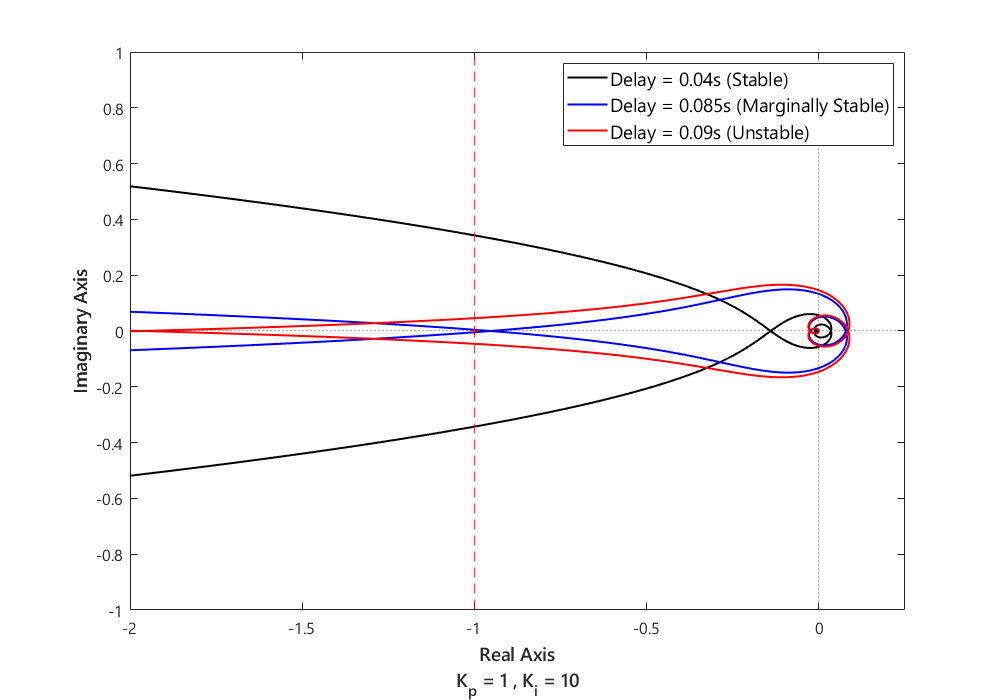

%PI controller
Kp = 1;
Ki = 10;
C_tf = tf([Kp Ki],[1 0]);

%Delay
td = [0.04 0.086 0.093];
linecolors = [{'k'} {'b'} {'r'}];
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
hold on
w = logspace(0,11,1000);
for i = 1:size(td,2)
    %Delay (Pade approximation)
    [nump,denp]=pade(td(i),3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    
end
plot(-1,0,'r+')
xlim([-2,.25])
ylim([-1,1])
yline(0,':');
xline(0,':');
xline(-1,'r--');
hold off
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel({'Real Axis','K_p = 1 , K_i = 10'},'FontName','Segoe UI Semibold','FontSize',14)
ylabel('Imaginary Axis','FontName','Segoe UI Semibold','FontSize',14)
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'Delay = 0.04s (Stable)','Delay = 0.085s (Marginally Stable)','Delay = 0.09s (Unstable)'},'FontName','Segoe Ui','FontSize',14)
box on

## Nyquist (Proportional Gain)

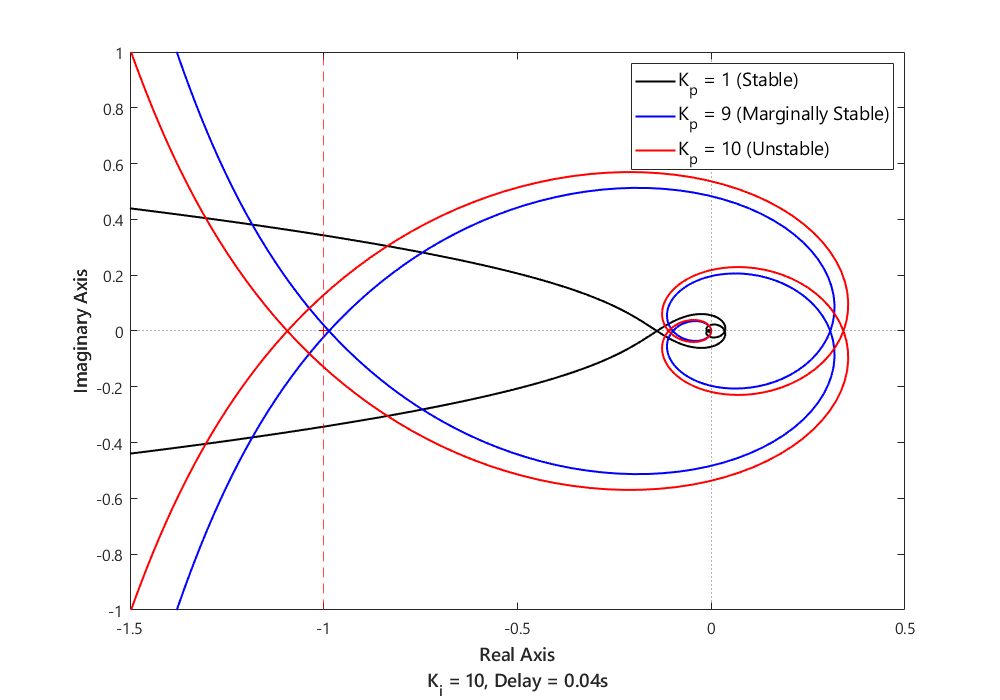

%PI controller
Kp = [1 9 10];
Ki = 10;


%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
hold on
w = logspace(0,11,1000);
for i = 1:size(Kp,2)
    C_tf = tf([Kp(i) Ki],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    
end
plot(-1,0,'r+')
xlim([-1.5,.5])
ylim([-1,1])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel({'Real Axis','K_i = 10, Delay = 0.04s'},'FontName','Segoe UI Semibold','FontSize',14)
ylabel('Imaginary Axis','FontName','Segoe UI Semibold','FontSize',14)
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_p = 1 (Stable)','K_p = 9 (Marginally Stable)','K_p = 10 (Unstable)'},'FontName','Segoe Ui','FontSize',14)
box on

## Nyquist (Integral Gain)

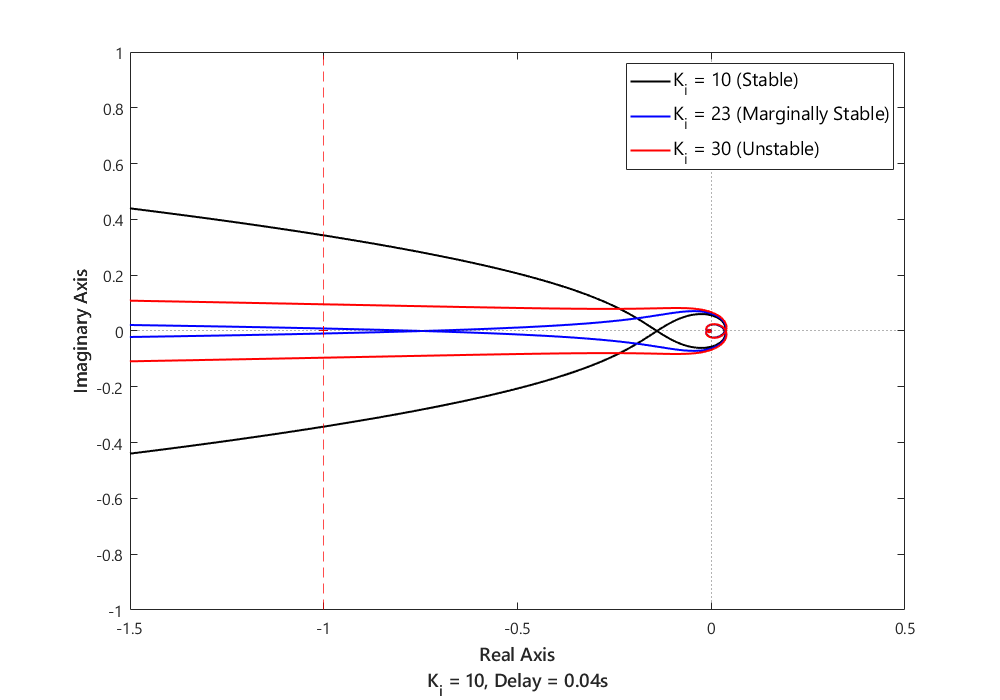

%PI controller
Kp = 1;
Ki = [10 23 30];


%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
hold on
w = logspace(0,11,1000);
for i = 1:size(Ki,2)
    C_tf = tf([Kp Ki(i)],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    
end
plot(-1,0,'r+')
xlim([-1.5,.5])
ylim([-1,1])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel({'Real Axis','K_i = 10, Delay = 0.04s'},'FontName','Segoe UI Semibold','FontSize',14)
ylabel('Imaginary Axis','FontName','Segoe UI Semibold','FontSize',14)
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_i = 10 (Stable)','K_i = 23 (Marginally Stable)','K_i = 30 (Unstable)'},'FontName','Segoe Ui','FontSize',14)
box on

## Bode Plot (Delay 0.04, Ki = 10, Kp = 1)

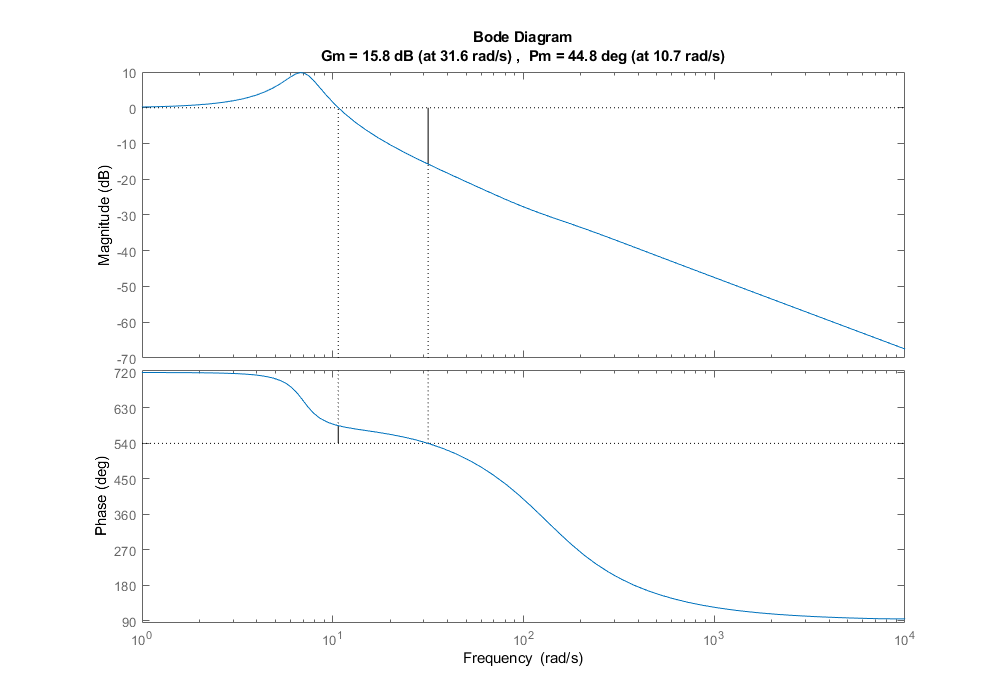

%PI controller
Kp = 1;
Ki = 10;
C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td = 0.04;
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

%Open and Closed Loop Transfer Functions
num = C_tf*G_plant*d_tf;
oltf = minreal(num);
den = (1 + oltf);
cl_tf = num/den;

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
margin(cl_tf)

## Delay Stability Surface

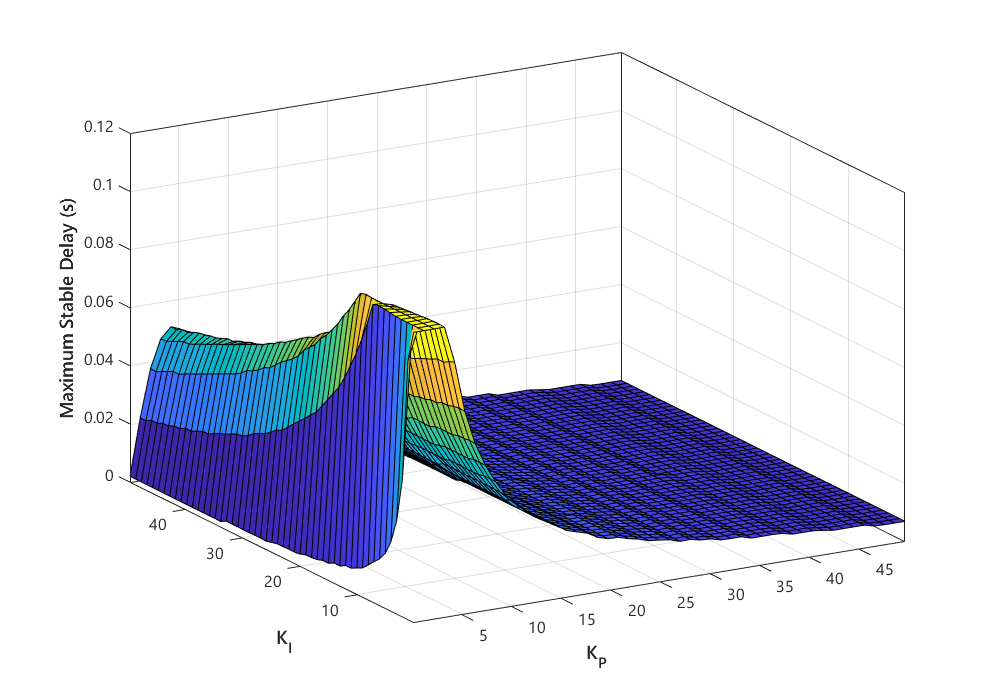

sf = fit([stabletip(:,1), stabletip(:,2)],stabletip(:,3),'cubicinterp');
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
set(gcf, 'Color', 'w');
plot(sf)% [stabletip(:,1), stabletip(:,2)],stabletip(:,3))
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Maximum Stable Delay (s)','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-30,25)

if eftoggle == 1
    export_fig maxdelaysurf2.emf
end


# Performance Plots

## Time

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

## Input Signal 1: Chirp

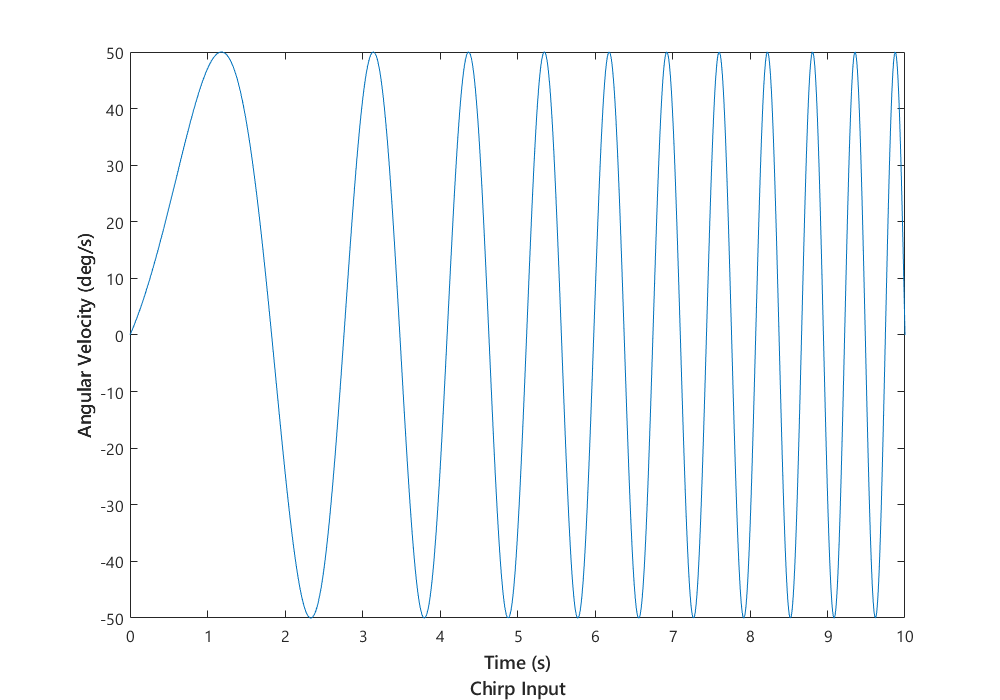

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,chirps)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel({'Time (s)','Chirp Input'},'FontName','Segoe UI Semibold','FontSize',14)
ylabel('Angular Velocity (deg/s)','FontName','Segoe UI Semibold','FontSize',14)

## Input Signal 2: SoS

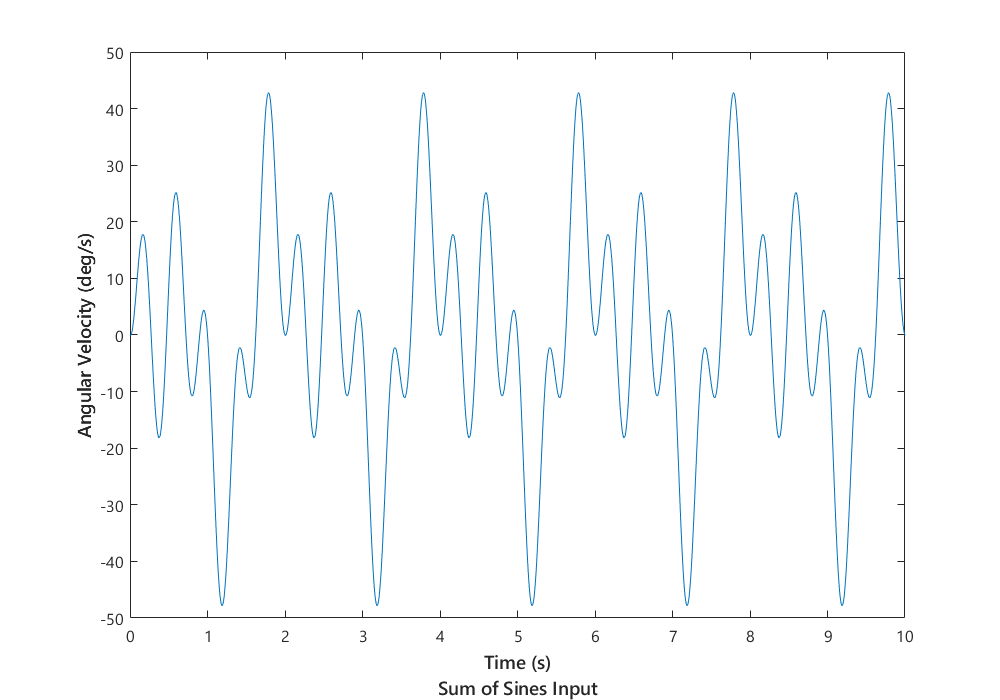

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,sos)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel({'Time (s)','Sum of Sines Input'},'FontName','Segoe UI Semibold','FontSize',14)
ylabel('Angular Velocity (deg/s)','FontName','Segoe UI Semibold','FontSize',14)

## Input Signal 3: Step

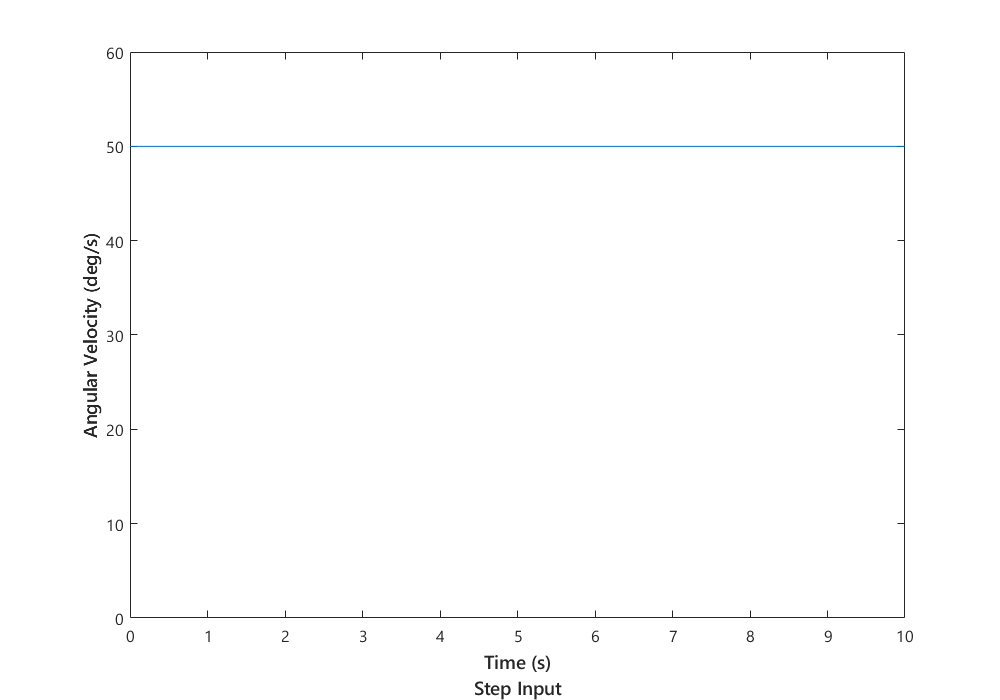

stepin = scale*ones(size(t));
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,stepin)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel({'Time (s)','Step Input'},'FontName','Segoe UI Semibold','FontSize',14)
ylabel('Angular Velocity (deg/s)','FontName','Segoe UI Semibold','FontSize',14)
ylim([0,60])

## 0.04 Delay (standard for fly)

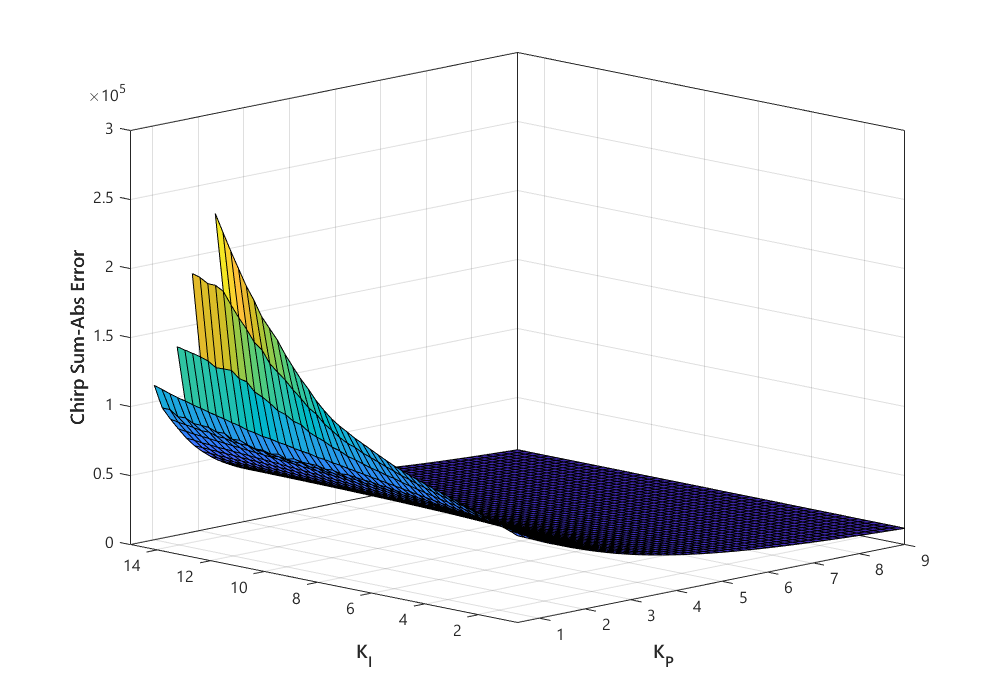

ind04 = 1;

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chirperror04 = zerostrip(chirperror(:,:,ind04));
sfchirp = fit([chirperror04(:,1),chirperror04(:,2)],chirperror04(:,3),'cubicinterp');
plot(sfchirp)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Chirp Sum-Abs Error','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-45,15)
set(gcf, 'Color', 'w');

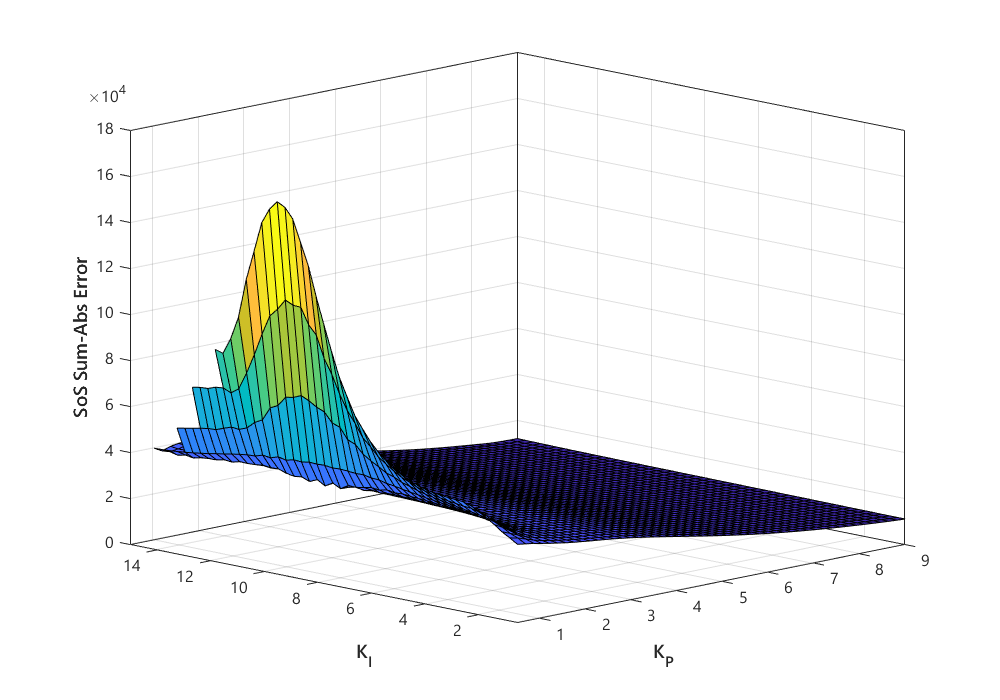

if eftoggle == 1
   export_fig chirpsse.emf 
end



figure('Renderer', 'painters', 'Position', [10 10 1000 700])
soserror04 = zerostrip(soserror(:,:,ind04));
sfsos = fit([soserror04(:,1),soserror04(:,2)],soserror04(:,3),'cubicinterp');
plot(sfsos)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('SoS Sum-Abs Error','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-45,15)
set(gcf, 'Color', 'w');

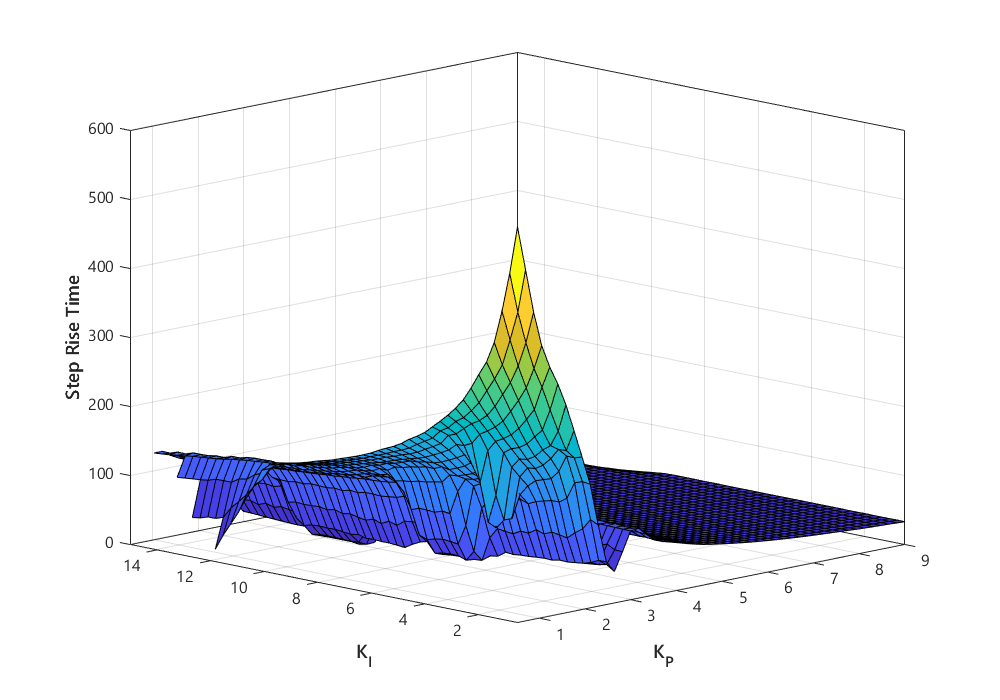

if eftoggle == 1
    export_fig sossse.emf    
end


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
risetime04 = zerostrip(strisetime(:,:,ind04));
sfrisetime = fit([risetime04(:,1),risetime04(:,2)],risetime04(:,3),'cubicinterp');
plot(sfrisetime)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Step Rise Time','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-45,15)
set(gcf, 'Color', 'w');

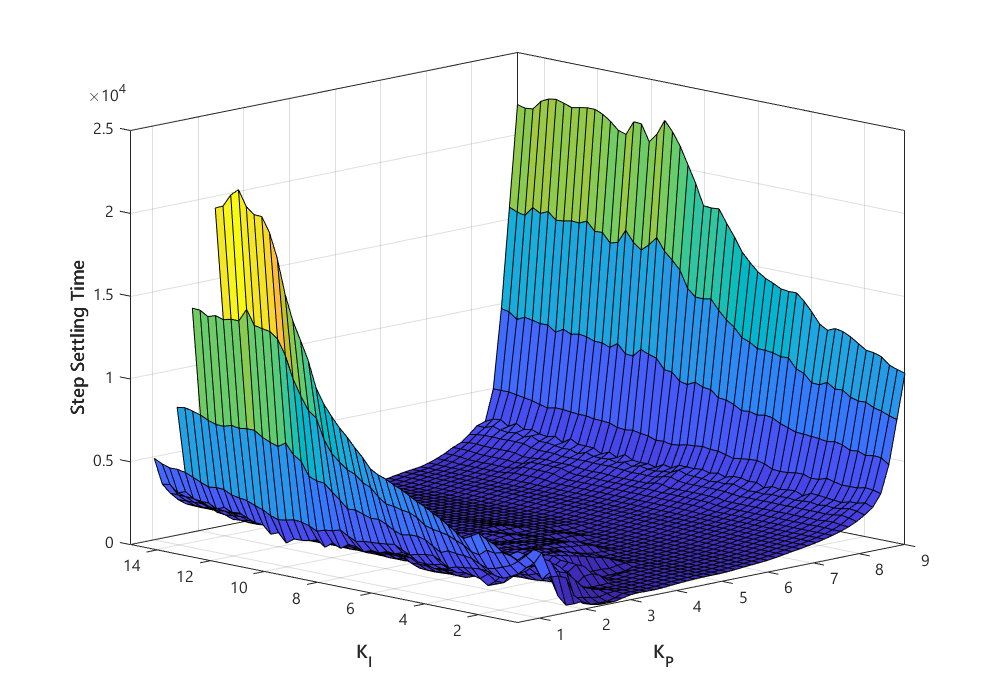

if eftoggle == 1
    export_fig risetime.emf    
end


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
settlingtime04 = zerostrip(stsettlingtime(:,:,ind04));
sfsettlingtime = fit([settlingtime04(:,1),settlingtime04(:,2)],settlingtime04(:,3),'cubicinterp');
plot(sfsettlingtime)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Step Settling Time','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-45,15)
set(gcf, 'Color', 'w');

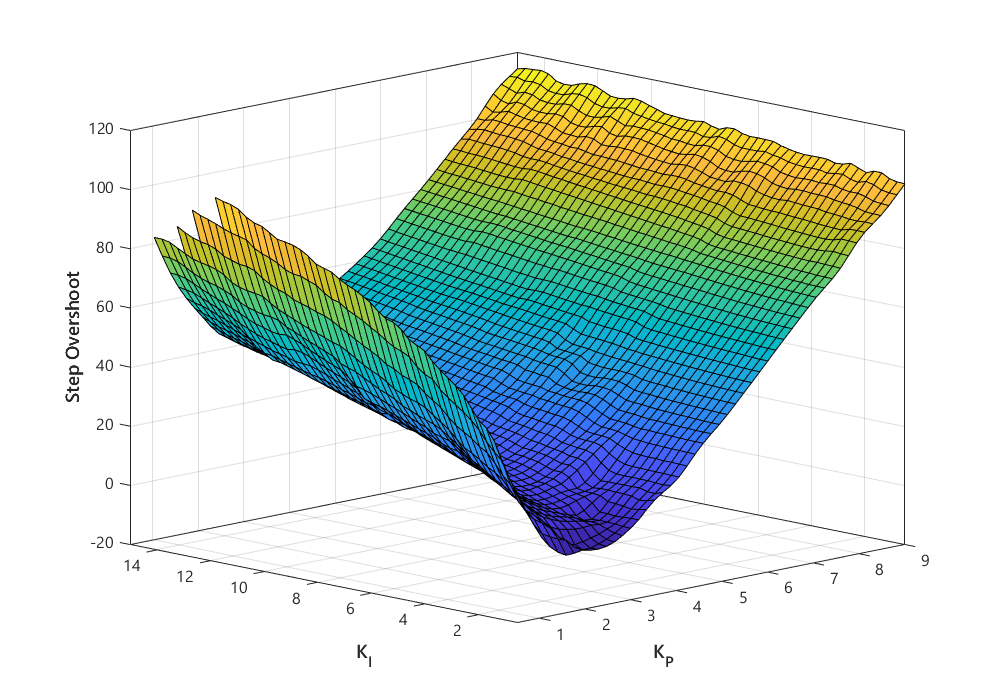

if eftoggle == 1
   export_fig settlingtime.emf 
end


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
overshoot04 = zerostrip(stovershoot(:,:,ind04));
sfovershoot = fit([overshoot04(:,1),overshoot04(:,2)],overshoot04(:,3),'cubicinterp');
plot(sfovershoot)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Step Overshoot','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-45,15)
set(gcf, 'Color', 'w');

if eftoggle == 1
    export_fig overshoot.emf
end


## Normalized, Weighted Surface

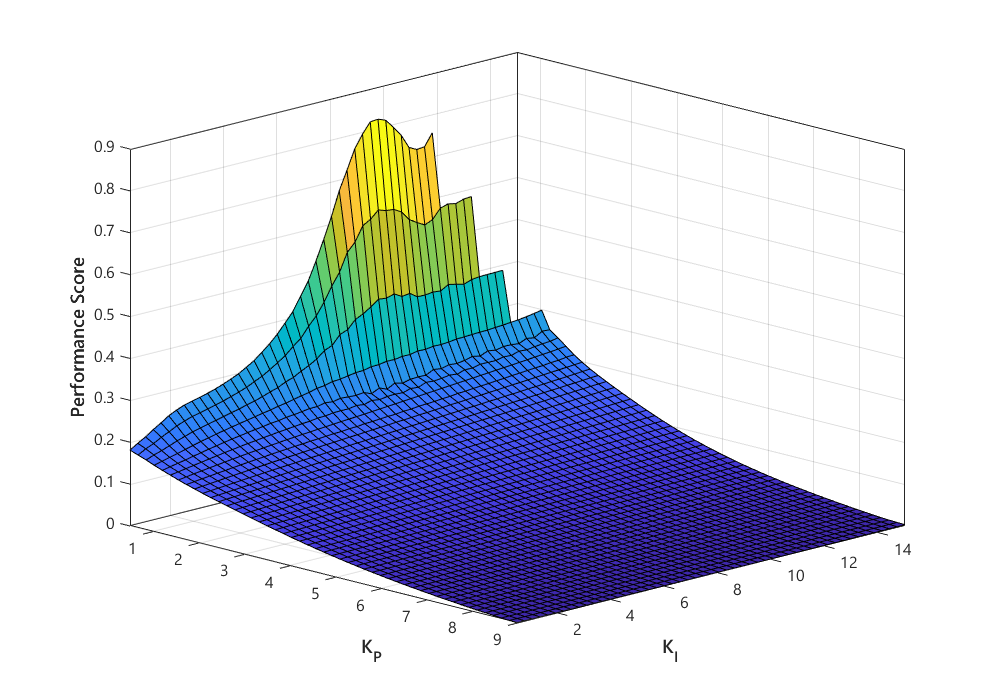

weights = [0.5 0.5 0 0 0]'; %Chirp SSE, SoS SSE, Rise, Settling, Overshoot
normchirpses = normalize(chirperror04(:,3),'range');
normsosses = normalize(soserror04(:,3),'range');
normrisetime = normalize(risetime04(:,3),'range');
normsettlingtime = normalize(settlingtime04(:,3),'range');
normovershoot = normalize(overshoot04(:,3),'range');
norms = [normchirpses normsosses normrisetime normsettlingtime normovershoot];
composite = norms*weights;

sfcomposite = fit([overshoot04(:,1),overshoot04(:,2)],composite,'cubicinterp');

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(sfcomposite)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Performance Score','FontName','Segoe UI Semibold','FontSize',14)
box on
view(45,20)
set(gcf, 'Color', 'w');

if eftoggle == 1
   export_fig composite.emf 
end


[minimum,index] = min(composite)

minimum = 0

index = 30

minKp = overshoot04(index,1)

minKp = 9

minKi = overshoot04(index,2)

minKi = 0.5000

## Optimal Response Based on weighting

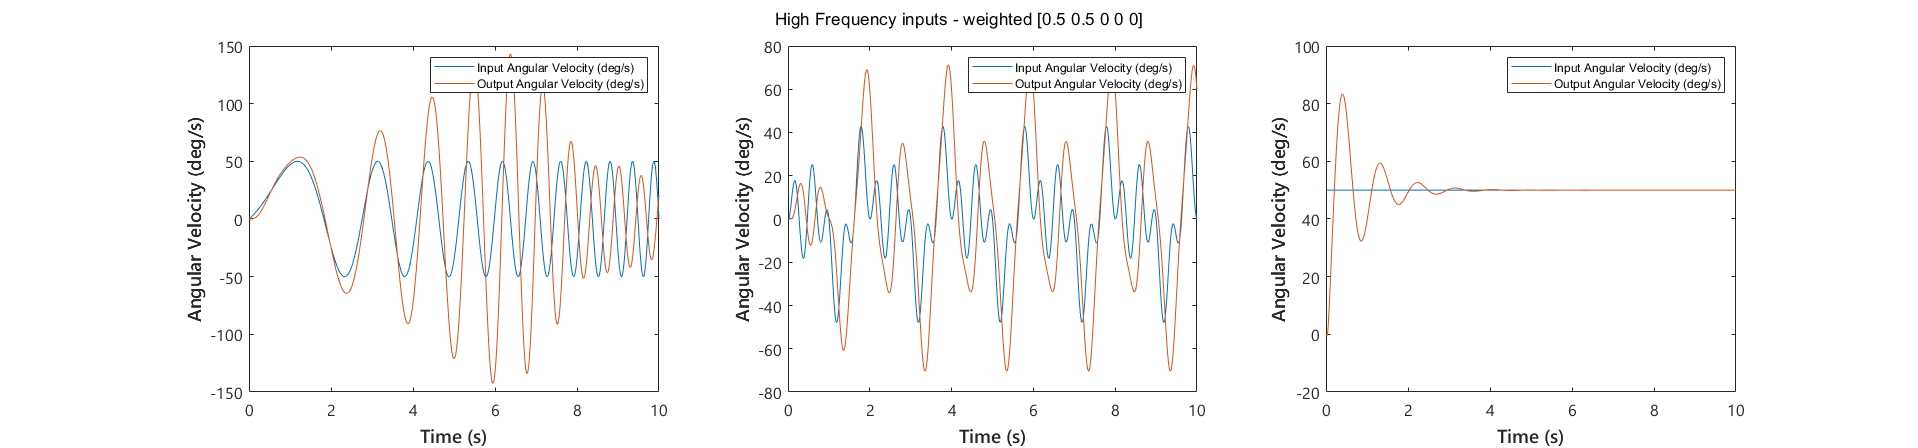

%C_tf = tf([minKp minKi],[1 0]);
C_tf = tf([1 10],[1 0]);
%Delay (Pade approximation)
td =.04;
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant*d_tf;
oltf = minreal(num);
den = (1 + oltf);
cl_tf = num/den;

chirpsim = lsim(cl_tf,chirps,t);
sossim = lsim(cl_tf,sos,t);
stepsim = lsim(cl_tf,stepin,t);

figure('Renderer', 'painters', 'Position', [10 10 3000 700])
subplot(1,3,1)
plot(t,chirps,t,chirpsim)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel('Time (s)','FontName','Segoe UI Semibold','FontSize',14)
ylabel('Angular Velocity (deg/s)','FontName','Segoe UI Semibold','FontSize',14)
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');

subplot(1,3,2)
plot(t,sos,t,sossim)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel('Time (s)','FontName','Segoe UI Semibold','FontSize',14)
ylabel('Angular Velocity (deg/s)','FontName','Segoe UI Semibold','FontSize',14)
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');

subplot(1,3,3)
plot(t,stepin,t,stepsim)
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
xlabel('Time (s)','FontName','Segoe UI Semibold','FontSize',14)
ylabel('Angular Velocity (deg/s)','FontName','Segoe UI Semibold','FontSize',14)
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');

sgtitle('High Frequency inputs - weighted [0.5 0.5 0 0 0]')